M=Model(false);%Create model without robot
in = zeros(1,4);%declaring in
in(1)=185;
in(2)=0;
in(3)=240;
in(4)=0;
out=M.robot.step2ik(in(1:3),in(4))%run the inverse kinimatics

out =          0  -42.1124   26.8575   15.2549


figure;%reset the plot before a new plot is made
result=M.plot_arm(out)%plot the result of running the forward kinimatics of the output of the inverse kinimatics

result =     1.0000         0         0  185.0000
         0    0.0000    1.0000   -0.0000
         0   -1.0000    0.0000  240.0000
         0         0         0    1.0000


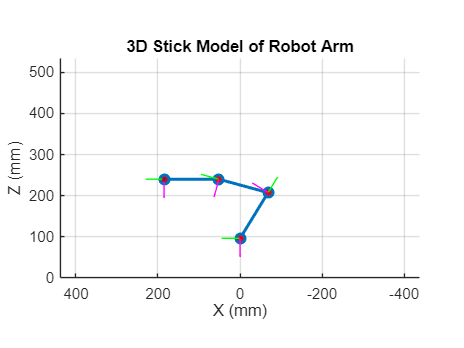

hold on;
plot3(in(1),in(2),in(3),'.','MarkerSize',10); %plot desired endpoint to compare with the resulting endpoint 

ee=result(1:3,4)' %get the end effector position out of the resulting transformation matrix

ee =   185.0000   -0.0000  240.0000


error=ee-in(1:3) %compare the resulting end effector position with the desired end effector position

error = 1.0e-13 *

    0.5684   -0.0880   -0.5684


errorNorm=norm(error) 

errorNorm = 8.0869e-14

Test new IK

NewOut=M.robot.step2ik2(in(1:3),in(4))

NewOut =          0  -42.1124   26.8575   15.2549


NewResult=M.fk(NewOut);
NewEE=NewResult'

NewEE =   185.0000
   -0.0000
  240.0000


NewError=NewEE'-in(1:3)

NewError = 1.0e-09 *

   -0.4781   -0.0000   -0.2929


NewErrorNorm=norm(NewError)

NewErrorNorm = 5.6070e-10

Time test

tic;
out=M.robot.step2ik(in(1:3),in(4));
oldTime=toc;
tic;
NewOut=M.robot.step2ik2(in(1:3),in(4));
newTIme=toc;
disp(oldTime)

    0.0022



disp(newTIme)

    0.0017



Test Traj

M.plot_arm(in);